# **GaudermannGD**

[Gudermannian function](https://en.wikipedia.org/wiki/Gudermannian_function) (hyperbolic amplitude function)

## Definition


$$\mathrm{gd}\;x\equiv \int_0^x \frac{\mathit{dt}}{\mathrm{cosh}\;t}={\mathrm{tan}}^{-1} \left(\mathrm{sinh}\;x\right)$$


Domain: $-\infty <x<\infty$. For the specified domain, the  codomain is the set of real numbers.

Special values:

   $\mathrm{gd}\left(0\right)=0$,   $\mathrm{gd}\left(\pm \infty \right)=\pm \frac{\pi }{2}$

Identities:


$$\mathrm{gd}\;x=2{\mathrm{tan}}^{-1} \left(\mathrm{tanh}\frac{x}{2}\right)$$


$\mathrm{cos}\;\mathrm{gd}\;x=\mathrm{sech}\;x$,   $\mathrm{sin}\;\mathrm{gd}\;x=\mathrm{tanh}\;x$

## Syntax

Y = GudermannGD(X)

y = gd(x)

## Description

**Y = GudermannGD(X)** returns the value of the Gudermannian function $\mathrm{gd}\;x$ for each element of the array  X .  X must be real array or scalar. **GudermannGD** is the wrapper function which calls the functions **gd** element-wise via the function **ufun1**.

**y = gd(x)** calculate the value of the  the lthe Gudermannian function $\mathrm{gd}\;x$  for the  x. It is assumed that  x is real scalars without check. y is NaN if x is invalid or convergence failed.

## Precision

## **Numerical Examples**

**Scalar input**

format long
x = 1/2; 
[gd(x), GudermannGD(x)]

ans =    0.480381079133729   0.480381079133729


Accuracy. 

fprintf('%.16g\n',gd(1)) 

0.8657694832396586


% Maple 0.8657694832396586 26

Special values

gd(0)

ans = 0

gd(-inf)/(pi/2)

ans = -1

gd(inf)/(pi/2)

ans = 1

Identities

x = 1/4;
disp(cos(gd(x))-1/cosh(x))

     1.110223024625157e-16



**Vector input**

x=[1e-6 2 3 1e20];
disp(sin(gd(x))- tanh(x))

     0     0     0     0



**Matrix input**

x=[-1/2 1/3 1/4; 1/2 -1/3 -1/4];
disp(gd(x)-2*atan(tanh(x/2)))

   1.0e-16 *

                   0  -0.555111512312578   0.277555756156289
                   0   0.555111512312578  -0.277555756156289



## **Plot**

**Example 1**

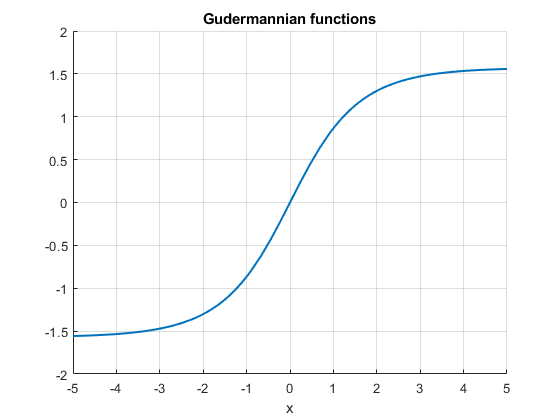

figure
hold on
fplot(@(x) GudermannGD(x),'LineWidth',1.5)
title('Gudermannian functions')
ylabel('')
xlabel('x')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

## **References**

## See Also